### Set up: -30

Read data

data_path = "Z:\Projects\РФФИ-Норвегия\Данные\Экспериментальные данные в лаборатории\Droplet freezing facility data\ThermoCalibration\";

main_data_name = "II_Desired -30_from +20_and back.csv";

thermo0_data_name = "II_Desired -30_from +20_and back_thermo0.csv";

main_table = readtable(strcat(data_path,main_data_name));

thermo0_table = readtable(strcat(data_path,thermo0_data_name));

% time when Pelletiers are switched off
time_cut = 1057678/60000;

Data preparing

main_table.time = main_table.time ./60000;
thermo0_table.time = thermo0_table.time ./60000;
main_table.edge_thermo = (main_table.thermo_1 + main_table.thermo_4)/2;
main_table.centre_thermo = (main_table.thermo_2 + main_table.thermo_3)/2;

fitObj = fit(thermo0_table.time(thermo0_table.time<=time_cut), ...
    thermo0_table.thermo_0(thermo0_table.time<=time_cut), 'cubicinterp');
time = 0:1:18;

Plotting

clf
plot(main_table.time(main_table.time<=time_cut), ...
    main_table.edge_thermo(main_table.time<=time_cut),'-blue')
xlabel('time, min');
ylabel('temperature, Celcius');
grid on;
grid(gca,'minor');
xlim([0,18]);
xticks(0:1:18);
title({"Substrate thermo regulation process", "Set up, Celcius: -30"});
hold on
plot(main_table.time(main_table.time<=time_cut), ...
    main_table.centre_thermo(main_table.time<=time_cut), '-red')
hold on
% data from controlling program
plot(thermo0_table.time(thermo0_table.time<=time_cut), ...
    thermo0_table.thermo_0(thermo0_table.time<=time_cut), ...
    'LineStyle','none','Marker','*')
hold on
plot(time,fitObj(time),'--r')

legend('edge','center','thermo control')

### Set up: 0

data_path = "Z:\Projects\РФФИ-Норвегия\Данные\Экспериментальные данные в лаборатории\Droplet freezing facility data\ThermoCalibration\";

main_data_name = "Desired 0.csv";

thermo0_data_name = "Desired 0_thermo0.csv";

main_table = readtable(strcat(data_path,main_data_name));

thermo0_table = readtable(strcat(data_path,thermo0_data_name));

Data preparing

main_table.time = main_table.time ./60000;
thermo0_table.time = thermo0_table.time ./60000;
main_table.edge_thermo = (main_table.thermo_1 + main_table.thermo_4)/2;
main_table.centre_thermo = (main_table.thermo_2 + main_table.thermo_3)/2;

fitObj = fit(thermo0_table.time, ...
    thermo0_table.thermo_0, 'linearinterp');
time = 2.5:1:66;

Plotting

clf
plot(main_table.time, ...
    main_table.edge_thermo,'-blue')
xlabel('time, min');
ylabel('temperature, Celcius');
grid on;
grid(gca,'minor');
xlim([0,66]);
xticks(0:2:66);
title({"Substrate thermo regulation process", "Set up, Celcius: 0"});
hold on
plot(main_table.time, ...
    main_table.centre_thermo, '-red')
hold on
% data from controlling program
plot(thermo0_table.time, ...
    thermo0_table.thermo_0, ...
    'LineStyle','none','Marker','*')
hold on
plot(time,fitObj(time),'--r')
hold on
plot([0 66],[0 0],'-.black')

legend('edge','center','thermo control')


### Set up: -5

data_path = "Z:\Projects\РФФИ-Норвегия\Данные\Экспериментальные данные в лаборатории\Droplet freezing facility data\ThermoCalibration\";

main_data_name = "Desired -5.csv";

thermo0_data_name = "Desired -5_thermo0.csv";

main_table = readtable(strcat(data_path,main_data_name));

thermo0_table = readtable(strcat(data_path,thermo0_data_name));

Data preparing

main_table.time = main_table.time ./60000;
thermo0_table.time = thermo0_table.time ./60000;
main_table.edge_thermo = (main_table.thermo_1 + main_table.thermo_4)/2;
main_table.centre_thermo = (main_table.thermo_2 + main_table.thermo_3)/2;

fitObj = fit(thermo0_table.time, ...
    thermo0_table.thermo_0, 'cubicspline');
time = 0.10:0.25:10.25;

Plotting

clf
plot(main_table.time, ...
    main_table.edge_thermo,'-blue')
xlabel('time, min');
ylabel('temperature, Celcius');
grid on;
grid(gca,'minor');
xlim([0,10.5]);
xticks(0:0.5:10.5);
title({"Substrate thermo regulation process", "Set up, Celcius: -5"});
hold on
plot(main_table.time, ...
    main_table.centre_thermo, '-red')
hold on
% data from controlling program
plot(thermo0_table.time, ...
    thermo0_table.thermo_0, ...
    'LineStyle','none','Marker','*')
hold on
plot(time,fitObj(time),'--r')
hold on
plot([0 10.5],[-5 -5],'-.black')

legend('edge','center','thermo control')

### Set up: -10

data_path = "Z:\Projects\РФФИ-Норвегия\Данные\Экспериментальные данные в лаборатории\Droplet freezing facility data\ThermoCalibration\";

main_data_name = "Desired -10.csv";

thermo0_data_name = "Desired -10_thermo0.csv";

main_table = readtable(strcat(data_path,main_data_name));

thermo0_table = readtable(strcat(data_path,thermo0_data_name));

Data preparing

main_table.time = main_table.time ./60000;
thermo0_table.time = thermo0_table.time ./60000;
main_table.edge_thermo = (main_table.thermo_1 + main_table.thermo_4)/2;
main_table.centre_thermo = (main_table.thermo_2 + main_table.thermo_3)/2;

fitObj = fit(thermo0_table.time, ...
    thermo0_table.thermo_0, 'smoothingspline');
time = 0.10:0.25:12.0;

Plotting

clf
plot(main_table.time, ...
    main_table.edge_thermo,'-blue')
xlabel('time, min');
ylabel('temperature, Celcius');
grid on;
grid(gca,'minor');
xlim([0,13.0]);
xticks(0:0.5:13.0);
title({"Substrate thermo regulation process", "Set up, Celcius: -10"});
hold on
plot(main_table.time, ...
    main_table.centre_thermo, '-red')
hold on
% data from controlling program
plot(thermo0_table.time, ...
    thermo0_table.thermo_0, ...
    'LineStyle','none','Marker','*')
hold on
plot(time,fitObj(time),'--r')
hold on
plot([0 13],[-10 -10],'-.black')

legend('edge','center','thermo control')

### Set up: -15

data_path = "Z:\Projects\РФФИ-Норвегия\Данные\Экспериментальные данные в лаборатории\Droplet freezing facility data\ThermoCalibration\";

main_data_name = "Desired -15.csv";

thermo0_data_name = "Desired -15_thermo0.csv";

main_table = readtable(strcat(data_path,main_data_name));

thermo0_table = readtable(strcat(data_path,thermo0_data_name));

Data preparing

main_table.time = main_table.time ./60000;
thermo0_table.time = thermo0_table.time ./60000;
main_table.edge_thermo = (main_table.thermo_1 + main_table.thermo_4)/2;
main_table.centre_thermo = (main_table.thermo_2 + main_table.thermo_3)/2;

fitObj = fit(thermo0_table.time, ...
    thermo0_table.thermo_0, 'smoothingspline');
time = 0.10:0.25:12.0;

Plotting

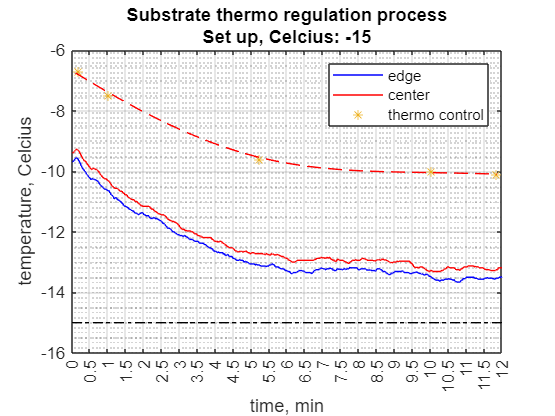

clf
plot(main_table.time, ...
    main_table.edge_thermo,'-blue')
xlabel('time, min');
ylabel('temperature, Celcius');
grid on;
grid(gca,'minor');
xlim([0,12.0]);
xticks(0:0.5:12.0);
title({"Substrate thermo regulation process", "Set up, Celcius: -15"});
hold on
plot(main_table.time, ...
    main_table.centre_thermo, '-red')
hold on
% data from controlling program
plot(thermo0_table.time, ...
    thermo0_table.thermo_0, ...
    'LineStyle','none','Marker','*')
hold on
plot(time,fitObj(time),'--r')
hold on
plot([0 12],[-15 -15],'-.black')

legend('edge','center','thermo control')